# Asteroid Optical Navigation

ASEN 5044 Final Project Description

*Group Members: *James Monaco, AJ Cuddeback, Grant Kirchoff

## Part 1: Deterministic System Analysis

### 1. Nonlinear Simulation

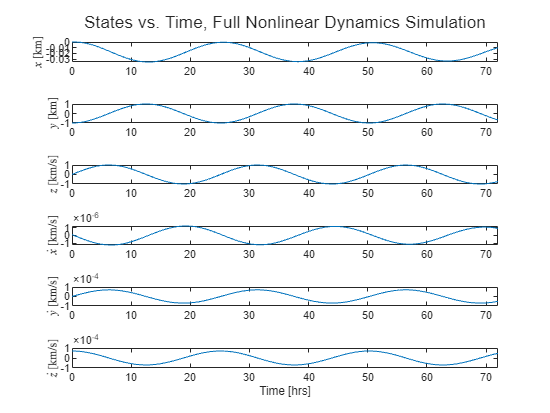

% bringing in simulation data and provided data
run('sim_setup.m')
load orbitdetermination-finalproj_data_2023_11_14.mat

% solar radiation pressure 
a_SRP = -Phi_0 / norm(r_S)^2 * (1 + 4/9 * rho) * A_M * r_S / norm(r_S);

% non-linear simualtion
x_pert = [1e-5,1e-5,1e-5,1e-7,1e-7,1e-7]'
x_0 = [r_nom; dr_nom] + x_pert;
options = odeset('RelTol',1e-12);
t_obs = unique(y_table(:, 1));  % [s]
[t_ode45,x_ode45] = ode45(@(t_in,x_in) orbit(t_in,x_in,a_SRP,mu_A), t_obs, x_0, options);
[steps,n] = size(x_ode45);

% plotting non-linear simulation solution
figure;
fig = tiledlayout(n,1);
ylabels = ["$x$ [km]", "$y$ [km]","$z$ [km/s]","$\dot x$ [km/s]", "$\dot y$ [km/s]","$\dot z$ [km/s]"];
for i = 1:n
    nexttile(fig)
    plot(t_ode45/60/60,x_ode45(:,i))
    xlim([t_obs(1)/60/60, t_obs(end)/60/60])
    ylabel(ylabels(i),Interpreter='latex')
end
xlabel("Time [hrs]")
title(fig,"States vs. Time, Full Nonlinear Dynamics Simulation")

### **2. Measurement Model**

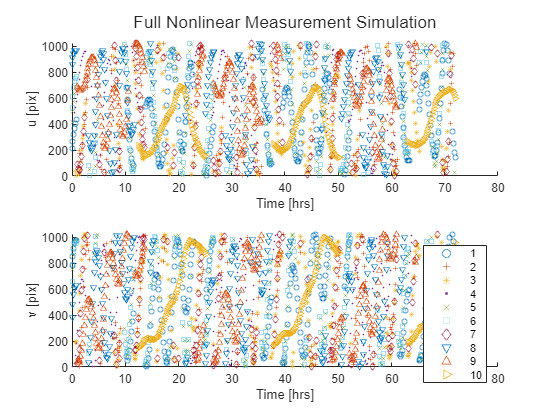

% setting things nup
r = x_ode45(:, 1:3)';               % xyz coords of satellite
[~,num_lmks] = size(pos_lmks_A);
u_obs = zeros(num_lmks,steps);
v_obs = zeros(num_lmks,steps);
for i = 1:num_lmks                  % perform observations for each landmark...
    l = pos_lmks_A(:,i);
    utot = zeros(1, steps);
    vtot = zeros(1, steps);
    for jj=1:steps                  % ... at each time step
        RNC = R_CtoN(:, :, jj);
        % w_A is stupid, and is a periodicity [sec/rot]
        % 1/period * sec is number of rotations
        % rotations * 2 * pi is radians 
        th = 2* pi * 1/w_A * t_obs(jj);  % [deg]
        R_NA = [cos(th) -sin(th) 0; 
                sin(th) cos(th)  0; 
                0       0        1];
        [u, v] = measure(l, r(:, jj), RNC, u_0, v_0, f, R_NA);
        utot(1, jj) = u;
        vtot(1, jj) = v;
    end
    u_obs(i,:) = utot;
    v_obs(i,:) = vtot;
end

% plotting observations
figure
fig = tiledlayout(2,1);
mkrs = ["o","+","*",".","x","square","diamond","v","^",">"];
sz = 15; 

% plotting u data
nexttile(fig)
hold on 
for i = 1:10
    s = scatter(t_obs/60/60,u_obs(i,:),mkrs(i));
    s.SizeData = sz;
end
hold off
xlabel('Time [hrs]')
ylabel('u [pix]')

% plotting v data
nexttile(fig)
hold on 
for i = 1:10
    s = scatter(t_obs/60/60,v_obs(i,:),mkrs(i));
    s.SizeData = sz;
end
hold off

% formatting
xlabel('Time [hrs]')
ylabel('v [pix]')
legend(string(1:10))
title(fig,"Full Nonlinear Measurement Simulation")

### 4. Simlation of DT linearized Model

No process noise, no measurement nose, no control input perturbations

% CT B matrix
m = length(a_SRP);
B = zeros(n,m);
B(4:end,:) = eye(3);

% performing the simulation
dx_DT = zeros(steps,n); 
dx_DT(1,:)= x_pert';
x_nom_0 = [r_nom', dr_nom'];
x_DT = zeros(steps,n);
for k = 1:steps-1
    % calculating nominal state
    x_nom_k = x_nom(x_nom_0,t_obs(k))';
    
    % Jacobians for nominal state
    dFdx_nom = dfdx(x_nom_k,mu_A);

    % Putting this in the discrete time 
    A = dFdx_nom;
    A_hat = zeros(n+m,n+m);
    A_hat(1:n,1:n) = A;
    A_hat(1:n,(n+1):end) = B;
    exmp_A_hat = expm(A_hat*dt_obs);
    F = exmp_A_hat(1:n,1:n);
    G = exmp_A_hat(1:n,(n+1):end);
    
    % deviation at the next time step
    dx_k_plus = F*dx_DT(k,:)'+ G*a_SRP;

    % saving these 
    dx_DT(k+1,:) = dx_k_plus';
    x_DT(k,:) = x_nom_k + dx_DT(k,:);
end
% calculating for the last time step
x_nom_k = x_nom(x_nom_0,t_obs(k+1))';
x_DT(k+1,:) = x_nom_k + dx_DT(k+1,:);

Plotting the DT LTI corrections over time:

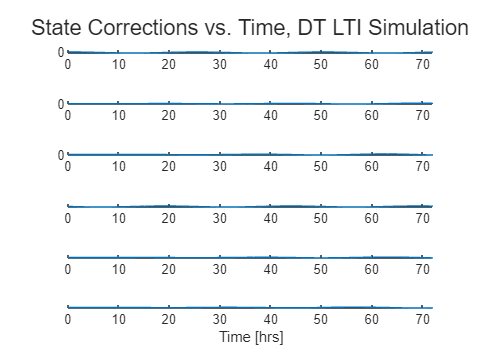

% plotting linear simulation solution
figure;
fig = tiledlayout(n,1);
ylabels = ["$\Delta x$ [km]", "$\Delta y$ [km]","$\Delta z$ [km/s]","$\Delta \dot x$ [km/s]", "$\Delta \dot y$ [km/s]","$\Delta \dot z$ [km/s]"];
for i = 1:n
    nexttile(fig)
    hold on
    plot(t_ode45/60/60,dx_DT(:,i))
    xlim([t_obs(1)/60/60, 72])
    ylabel(ylabels(i),Interpreter='latex')
end
xlabel("Time [hrs]")
title(fig,"State Corrections vs. Time, DT LTI Simulation")

Validating against full nonlinear simulation: 

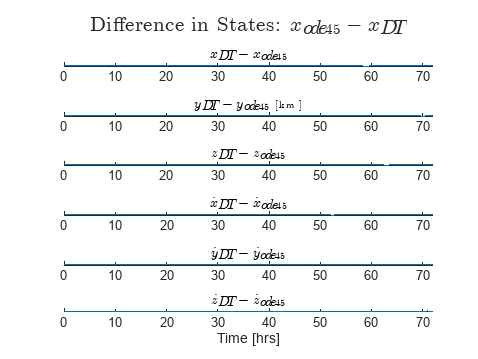

% plotting linear simulation solution
figure;
fig = tiledlayout(n,1);
titles =   ["$x_{DT} - x_{ode45}$", "$y_{DT} - y_{ode45}$ [km]","$z_{DT} - z_{ode45}$", ...
            "$\dot x_{DT} - \dot x_{ode45}$", "$\dot y_{DT} - \dot y_{ode45}$","$\dot z_{DT} - \dot z_{ode45}$"];
ylabels =   ["$\Delta x$ [km]", "$\Delta y$ [km]","$\Delta z$ [km/s]", ...
            "$\Delta \dot x$ [km/s]", "$\Delta \dot y$ [km/s]","$\Delta \dot z$ [km/s]"];
for i = 1:n
    nexttile(fig)
    hold on
    plot(t_ode45/60/60,x_DT(:,i)-x_ode45(:,i))
    hold off
    xlim([t_obs(1)/60/60, 72])
    title(titles(i),Interpreter='latex')
    ylabel(ylabels(i),Interpreter='latex')
end
xlabel("Time [hrs]")
title(fig,"Difference in States: $x_{ode45} - x_{DT}$", Interpreter='latex')

Discrete Linearized Measrement Plotting

H_1_1 = H_l_k(pos_lmks_A(:,1),x_0(1:3),1,f,w_A, t_obs,RNC); 

Unrecognized function or variable 'H_l_k'.

m = 2; % 2 meausrement dimensions
y_1 = H_1_1*dx_DT(1,:)'; 
dy_DT = nan(num_lmks,steps,m); % at landmark l and step k, dy is a row vector
% for each one, calculate H matrix and plot
ylabels = ["$\Delta u$ [pixels]", "$\Delta v$ [pixels]"]
l1vis = zeros(1,steps);
uv = nan(steps,2);
for li = 1  %start by just doing this for the 1st landmark
    figure;
    fig = tiledlayout(2,1)
    l = pos_lmks_A(:,li);
    for ki = 1:steps
        RNC = R_CtoN(:,:,ki); % get the RNC matrix for that time step
        R_NA = R_NA_k(ki,w_A,t_obs); % get the RNA matrix for that time step
        r = x_nom_vec(ki,1:3)';
%         r = x_ode45(ki, 1:3)';
        % check to see if landmark is in field of view
%         l_vis = l_visible(l,r,RNC,0,0,f,R_NA);
        [u, v] = measure(l,r,RNC,u_0,v_0,f,R_NA);
        meas = [u,v];
        uv(ki,:) = [u,v];
        if anynan(meas) == 0 % if object is in field of view
            H_ll_kk = H_l_k(l,r,ki,f,w_A,t_obs,RNC);
            dy_l_k = H_ll_kk*dx_DT(ki,:)'; % get dy for that location
            dy_DT(li,ki,:) = (dy_l_k)'; % save it
            l1vis(ki) = 1; % this is just for landmark 1
        end  % if l_vis is 1, save, if not, stay nan
    end
    for i = 1:2
        nexttile(fig),hold on, grid on
        plot(t_ode45/60/60,dy_DT(li,:,i),'.')
        xlim([t_obs(1)/60/60, 72])
        ylabel(ylabels(i),Interpreter='latex')
    end
end 

figure; 
l1vis_orig = ones(1,length(u_obs(1,:)))-isnan(u_obs(1,:))
plot(t_ode45/60/60,l1vis), hold on
plot(t_ode45/60/60,l1vis_orig,'--')
xlim([t_obs(1)/60/60, 72])
ylabel("Landmark 1 Visible (binary)")
title("Visibility of Landmark 1")
legend(["Perturbation","Original Observation"])
xlabel("Time, t [hours]")

## Part 2: Stochastic Nonlienar Filtering

### Discrete Time State Evolution with Process Noise

% CT B matrix
m = length(a_SRP);
B = zeros(n,m);
B(4:end,:) = eye(3);

% CT Gamma matrix 
Gamma = zeros(n,m);
Gamma(4:end,:) = eye(3);

% CT Noise
W = eye(3)*sig_w^2;

% performing the simulation
dx_DT = zeros(steps,n); 
dx_DT(1,:)= x_pert';
x_nom_0 = [r_nom', dr_nom'];
x_DT = zeros(steps,n);

% generating seeds for the simulation
rng(100)    % Seed for the noise creation seed
seeds = round(rand([1,steps]) * 100); % used to make sure the input noise is the same each time 

for k = 2:steps
    % calculating nominal state
    x_nom_k = x_nom(x_nom_0,t_obs(k))';
    
    % Jacobians for nominal state
    A = dfdx(x_nom_k,mu_A);

    % Putting this in the discrete time 
    [F,G,w_k] = state_CT_to_DT(dt_obs,A,B,Gamma,W,seeds(k));
    
    % deviation at the next time step
    dx_k_plus = F*dx_DT(k,:)'+ G*a_SRP + w_k;

    % saving these 
    dx_DT(k+1,:) = dx_k_plus';
    x_DT(k,:) = x_nom_k + dx_DT(k,:);
end

Non-linear simulation, with noise: 

% non-linear simualtion with noise
x_pert = [1e-5,1e-5,1e-5,1e-7,1e-7,1e-7]';
x_0 = [r_nom; dr_nom] + x_pert;
x_ode45_noise = zeros(steps,n); 
x_ode45_noise(1,:) = x_0;
options = odeset('RelTol',1e-12);
for k = 2:steps
    seed = seeds(k);
    [t_k,x_ode45_k] = ode45(@(t_in,x_in) orbit_noise(t_in,x_in,a_SRP,mu_A,W,seed), [t_obs(k-1), t_obs(k)], x_ode45_noise(k-1,:), options);
    x_ode45_noise(k,:) = x_ode45_k(end,:);
end

Validating against full nonlinear simulation: 

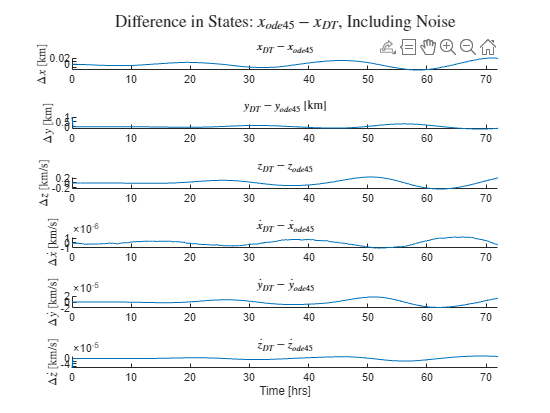

% plotting linear simulation solution
figure;
fig = tiledlayout(n,1);
titles =   ["$x_{DT} - x_{ode45}$", "$y_{DT} - y_{ode45}$ [km]","$z_{DT} - z_{ode45}$", ...
            "$\dot x_{DT} - \dot x_{ode45}$", "$\dot y_{DT} - \dot y_{ode45}$","$\dot z_{DT} - \dot z_{ode45}$"];
ylabels =   ["$\Delta x$ [km]", "$\Delta y$ [km]","$\Delta z$ [km/s]", ...
            "$\Delta \dot x$ [km/s]", "$\Delta \dot y$ [km/s]","$\Delta \dot z$ [km/s]"];
for i = 1:n
    nexttile(fig)
    hold on
    plot(t_ode45/60/60,x_DT(:,i)-x_ode45(:,i))
    hold off
    xlim([t_obs(1)/60/60, 72])
    title(titles(i),Interpreter='latex')
    ylabel(ylabels(i),Interpreter='latex')
end
xlabel("Time [hrs]")
title(fig,"Difference in States: $x_{ode45} - x_{DT}$, Including Noise", Interpreter='latex')

### 5. Linarized KF 

- Use specified nominal state trajectory, control inputs, and covariance matrix

-  Use NEES and NIS $\chi^2
$ test based on MC TMT simulations to tune and validate LKF

### 6. Extended KF 

### 7. Implement LKF and EKF for Estimation

function dx = orbit(~,x_in,a_SRP,mu_A)
    % calculating pertibation forces
    r = x_in(1:3);
    f = a_SRP + a_2B(r,mu_A);
    
    % building the derivative vector
    dx = zeros(size(x_in));
    dx(1:3) = x_in(4:6);
    dx(4:6) = f;
end

function dx = orbit_noise(~,x_in,a_SRP,mu_A,W,seed)
    % calculating pertibation forces
    r = x_in(1:3);
    rng(seed)
    noise = mvnrnd(zeros([1,3]),W)';
    f = a_SRP + a_2B(r,mu_A) + noise;
    
    % building the derivative vector
    dx = zeros(size(x_in));
    dx(1:3) = x_in(4:6);
    dx(4:6) = f;
end

function f = a_2B(r,mu_A)
    % calculating gravitational forces
    f = -mu_A / norm(r)^3 * r;
end 

function [u, v] = measure(l, r, RNC, u0, v0, f, R_NA)
    % calculate pixel coordinate of SC
    
    % unit vectors of camera coordinate system
    ihat = RNC(:, 1);
    jhat = RNC(:, 2);
    khat = RNC(:, 3);

    % transformed coords based on asteriod rotation
    % the coords of the satellite are in the inertial frame, and do NOT
    % require transformation 
    l = R_NA * l;
    
    % if the asteriod occuludes the object, return with no observations
    if l'*khat > 0
        u = NaN;
        v = NaN;
        return
    end
    
    % calculating coordinates of observation 
    u = f * ((l-r)'*ihat)/((l-r)'*khat) + u0;
    v = f * ((l-r)'*jhat)/((l-r)'*khat) + v0;

    % making sure object is within FOV
    if u<0 || u>1024 || v<0 || v>1024 || (l-r)'*khat < 0
        u = NaN;
        v = NaN;
    end
end

function dfdx_ij = dfdx_ij(r, i , j, mu_A)
    if i==j
        dfdx_ij  = mu_A * (3*r(i)^2/(norm(r)^5) - 1/(norm(r)^3));
    else
        dfdx_ij = 3*mu_A*r(i)*r(j)/(norm(r)^5);
    end
end

function dfdx = dfdx(r_nom,mu_A)
    dfdx =[ 0                          0                          0                            1   0   0;
            0                          0                          0                            0   1   0;
            0                          0                          0                            0   0   1;
            dfdx_ij(r_nom, 1, 1, mu_A) dfdx_ij(r_nom, 1, 2, mu_A) dfdx_ij(r_nom, 1, 3, mu_A)   0   0   0;
            dfdx_ij(r_nom, 2, 1, mu_A) dfdx_ij(r_nom, 2, 2, mu_A) dfdx_ij(r_nom, 2, 3, mu_A)   0   0   0;
            dfdx_ij(r_nom, 3, 1, mu_A) dfdx_ij(r_nom, 3, 2, mu_A) dfdx_ij(r_nom, 3, 3, mu_A)   0   0   0];
end 

function x_nom = x_nom(x_nom_0,t)
    r0 = norm(x_nom_0(1:3));
    w0 = x_nom_0(6) / r0;
    x_nom = [0;
            -r0 * cos(w0*t);
            r0 * sin(w0*t);
            0;
            w0*r0*sin(w0*t);
            w0*r0*cos(w0*t)];
end

function [F,G,w_k] = state_CT_to_DT(dt_obs,A,B,Gamma,W,seed)
    % finding number of state variables and inputs
    [n,m] = size(B);
    
    % converting to discrete time
    A_hat = zeros(n+m,n+m);
    A_hat(1:n,1:n) = A;
    A_hat(1:n,(n+1):end) = B;
    exmp_A_hat = expm(A_hat*dt_obs);
    G = exmp_A_hat(1:n,(n+1):end);

    % Simulating noise 
    Z = zeros(n*2,n*2);
    Z(1:n,1:n) = -A;
    Z((n+1):end,(n+1):end) = A';
    Z(1:n,(n+1):end) = Gamma * W * Gamma';
    expm_Z = expm(Z*dt_obs);
    F = expm_Z((n+1):end,(n+1):end)';
    Q_k = F * expm_Z(1:n,(n+1):end);
    rng(seed);
    w_k = mvnrnd(zeros(n,1),Q_k)';
end

function R_NA_k = R_NA_k(k,w_A,t_obs)
    th = 2* pi * 1/w_A * t_obs(k);  % [deg]
    R_NA_k = [cos(th) -sin(th) 0; 
            sin(th) cos(th)  0; 
            0       0        1];
end

% gives the h matrix for the nth landmark at the location ln
function H_n_k = H_n_k(ln, r, k,f, w_A,t_obs,RNC)

    RNA =  R_NA_k(k,w_A,t_obs);
    l = RNA * ln; % convert asteroid coordinates to inertial frame

    i = RNC(:,1); j = RNC(:,2); k = RNC(:,3);

    lr = (l-r)'; 
    lr_i = lr*i; lr_j = lr*j; lr_k = lr*k;

    % let c1 be the same term for all a1 and a2
    a1 = f*((lr_i/lr_k/lr_k)*k - (lr_i/lr_k/lr_k)*i);
    a2 = f*((lr_j/lr_k/lr_k)*k - (lr_j/lr_k/lr_k)*j);

    H_n_k = [a1' 0 0 0; 
         a2' 0 0 0];
end